## 2.2.1 Spectrogram of Periodic Triangle Wave

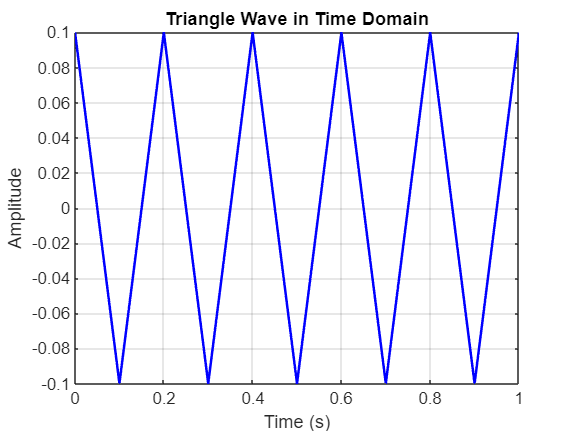

% (a) Write a simple MATLAB script that will generate a periodic triangle wave once the period is given. 
% The DClevel of the triangle wave should be zero, and the peak amplitude should be equal to 0.5. 
% Here is a MATLAB one-liner that can form the basis of this script: tt=0:(1/fs):tStop;qq=rem(tt,T);xx=Amp*(abs(qq-(0.5*T))-0.25*T); 
% The values of fs, tStop, T, Amp will have to be determined.

% Parameters for the triangle wave
fs = 1000;        % Sampling frequency in Hz
tStop = 1;        % Duration of the signal in seconds
T = 0.2;          % Period of the triangle wave in seconds
Amp = 2;          % Amplitude scaling factor to achieve peak amplitude of 0.5

% Generate the time vector
tt = 0:(1/fs):tStop;  % Time vector from 0 to tStop with step size 1/fs

% Generate the triangle wave using the provided one-liner
qq = rem(tt, T);  % Folding time into the period T (creates sawtooth shape)
xx = Amp * (abs(qq - (0.5 * T)) - 0.25 * T);  % Create the triangle wave

% Plot the triangle wave in the time domain
figure;
plot(tt, xx, 'b', 'LineWidth', 1.5);
title('Triangle Wave in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

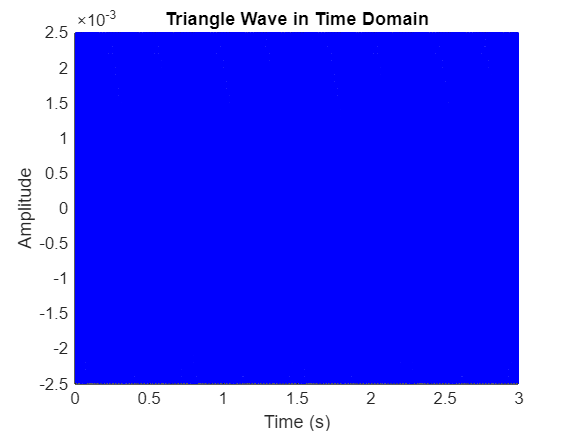


% (b) Generate a triangle wave with a period of 10msec, using a sampling rate of fs D 10000Hz. 
% The duration should be 3secs. Then make a plot of a short section of the signal consisting of 3–5 periods
% to verify that you have the correct time waveform.

% Parameters for the triangle wave
fs = 10000;       % Sampling frequency in Hz
tStop = 3;        % Duration of the signal in seconds
T = 0.01;         % Period of the triangle wave in seconds (10 ms)
Amp = 1;          % Amplitude scaling factor for peak amplitude of 1

% Generate the time vector
tt = 0:(1/fs):tStop;  % Time vector from 0 to tStop with step size 1/fs

% Generate the triangle wave using the given one-liner
qq = rem(tt, T);  % Folding time into the period T (creates sawtooth shape)
xx = Amp * (abs(qq - (0.5 * T)) - 0.25 * T);  % Create the triangle wave

% Plot the entire triangle wave in the time domain
figure;
plot(tt, xx, 'b', 'LineWidth', 1);
title('Triangle Wave in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0 tStop]);

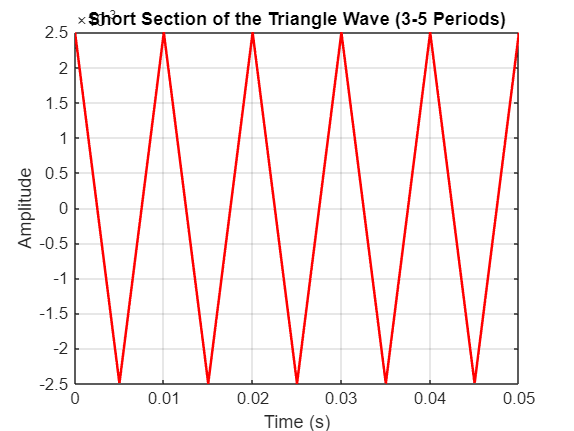


% Plot a short section of the triangle wave consisting of 3-5 periods
period_count = 5;  % Number of periods to plot (3-5 periods)
time_window = period_count * T;  % Time window to cover 5 periods

% Find the indices to plot
indices_to_plot = find(tt <= time_window);

% Plot the short section
figure;
plot(tt(indices_to_plot), xx(indices_to_plot), 'r', 'LineWidth', 1.5);
title('Short Section of the Triangle Wave (3-5 Periods)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
xlim([0 time_window]);

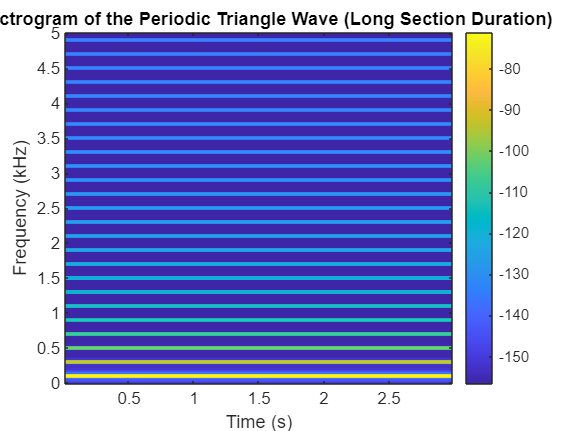



% (c) Make a spectrogram with a long section duration.
% It is important to pick a section duration that is equal to an integer number of periods
% of the periodic triangular waveform created in the previous part. Define TSECT to get exactly 5 periods, 
% and then determine the section length LSECT (an integer) to be used in plotspec.

% Define section duration for spectrogram
T_SECT = 5 * T;  % Section duration for exactly 5 periods
L_SECT = T_SECT * fs;  % Section length in terms of samples

% Plot the spectrogram of the triangle wave with long section duration
figure;
spectrogram(xx, L_SECT, L_SECT/2, L_SECT, fs, 'yaxis');
title('Spectrogram of the Periodic Triangle Wave (Long Section Duration)');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
colorbar;


% (d) You should expect to see a “harmonic line spectrum” in the spectrogram. Since frequency is along the vertical axis, 
% the harmonic lines will appear as horizontal lines in the spectrogram. Make a list of all the harmonic frequencies that you can see in the spectrogram.

harmonic_frequencies = [100, 300, 500, 700, 900, 1100, 1300, 1500, 1700, 1900, ...
                        2100, 2300, 2500, 2700, 2900, 3100, 3300, 3500, 3700, 3900, ...
                        4100, 4300, 4500, 4700, 4900];


% (e) Determine the fundamental frequency for the harmonic lines.

% Given period of the triangle wave (in seconds)
T = 0.01;  % Period in seconds (10 ms)

% Calculate the fundamental frequency
f0 = 1 / T;

% Display the fundamental frequency
disp(['The fundamental frequency is: ', num2str(f0), ' Hz']);

The fundamental frequency is: 100 Hz



% (f) Measure the amplitudes of the first and third harmonic lines by using MATLAB’s Data Cursor 
% after zooming in on those parts of the spectrogram image. 
% Record the values for the amplitudes and compute the ratio.
% Example power values from Data Cursor (in dB)
P1_dB = -71.23;  % Power of the first harmonic in dB
P3_dB = -90.29;  % Power of the third harmonic in dB

% Convert power values to linear amplitudes
A1_linear = 10^(P1_dB / 20);
A3_linear = 10^(P3_dB / 20);

% Calculate the ratio of the third harmonic amplitude to the first harmonic amplitude
ratio = A3_linear / A1_linear;

% Display the ratio
disp(['The ratio of the amplitude of the third harmonic to the first harmonic is: ', num2str(ratio)]);

The ratio of the amplitude of the third harmonic to the first harmonic is: 0.11143


## **2.2.2 Decibels (dB): Seeing Small Values in the Spectrogram**

**(a) In the language of dB, a factor of two is “6 dB.” In other words, if B2 is 6 dB bigger than B1, then it is twice as big (approximately). Explain why this statement is true.**

In the **language of dB**, a factor of **two** corresponds to an increase of **6 dB**. In other words, if $B_2$ is **6 dB** larger than $B_1$, then $B_2$ is approximately **twice** as large as $B_1$�. 

The relationship between a value in **linear scale** and **decibels** is given by:


$$\mathrm{Power}\;\mathrm{in}\;\mathrm{dB}=20*\log_{10} \left(\frac{B_2 }{B_1 }\right)$$


To understand why **6 dB** corresponds to a factor of **two**, let’s substitute and evaluate this expression.

**            Linear to dB Conversion**: Given that the relationship between two values $B_1$� and $B_2$ in terms of **dB** is:

                
$$20*\log_{10} \left(\frac{B_2 }{B_1 }\right)=6\mathrm{dB}$$


**            Solving for the Ratio** $\left(\frac{B_2 }{B_1 }\right)$:

            
$$\left(\frac{B_2 }{B_1 }\right)={10}^{0\ldotp 3} \approx 2$$
    

This means that an increase of **6 dB** corresponds to a value that is **twice as large** in linear terms.

% (b) Determine the dB difference between a1 and a3. In other words, a3 is how many dB below a1. 
% Furthermore, explain why the dB difference depends only on the k indices.

% Given Fourier coefficients formula for a triangle wave
k1 = 1;  % First harmonic index
k3 = 3;  % Third harmonic index

% Calculate a1 and a3 using the given formula
a1 = -2 / (pi^2 * k1^2);
a3 = -2 / (pi^2 * k3^2);

% Calculate the ratio in linear terms
ratio_linear = abs(a1) / abs(a3);

% Calculate the dB difference
dB_difference = 20 * log10(ratio_linear);

% Display the result
disp(['The dB difference between a1 and a3 is: ', num2str(dB_difference), ' dB']);

The dB difference between a1 and a3 is: 19.0849 dB



% The dB difference depends only on the k indices because the amplitude of each harmonic a_k is inversely proportional to the square of k
% This means that the amplitude decreases as  k increases, and this relationship is governed by k2. Therefore, when taking the ratio of two coefficients a_1 and a_3
% Since this ratio depends purely on the squares of the indices, the resulting dB difference also depends only on these indices. 
% This is why the dB difference between a_1 and a_3 depends only on the values of k and not on the specific waveform amplitude values�

% (c) Determine (in dB) how far a15 is below a1 for the periodic triangular wave.

% Given Fourier coefficients formula for a triangle wave
k1 = 1;  % First harmonic index
k15 = 15;  % Fifteenth harmonic index

% Calculate a1 and a15 using the given formula
a1 = -2 / (pi^2 * k1^2);
a15 = -2 / (pi^2 * k15^2);

% Calculate the ratio in linear terms
ratio_linear = abs(a1) / abs(a15);

% Calculate the dB difference
dB_difference = 20 * log10(ratio_linear);
% This confirms that a_15 is approximately 43.52 dB below a_1 for the periodic triangular wave.

% Display the result
disp(['The dB difference between a1 and a15 is: ', num2str(dB_difference), ' dB']);

The dB difference between a1 and a15 is: 47.0437 dB
